# Rosenzweig-Macarthur Universal Model

This code reproduces the figures in "Universal Allometry from empirical parameters"

There are a range of dependencies in the folder from the matlab code exchange; 

these are: stationary, hex2rgb, subtightplot and tightfig.

## Setup

Variables are frequently cleared however these two functions are used throughout to set base values.

% import a nice colour scheme
colourScheme

% Set base parameter values for coefficients and exponents 
% fast and convenient assignment/reset
assignBaseParameters_attackform

## Equilibria

#### Plot the base equilibria

This section creates the size-abundance plot with inset.

% reset params
clear
colourScheme
assignBaseParameters_attackform

% set exponents to empirical values
sigmab = 1/2;
sigmahR = 1/8;
sigmahC = -1/4;
sigmaK = -3/4;
    
% Set how many points for the results vectors
numPredators = 800;
numPPMR = 100;

% smallest (log) size 
minPredSize=-8;
% largest (log) size
maxPredSize = 6;
   
% min (log) PPMR
minPPMR=-4;
% max (log) PPMR
maxPPMR = 2;

% generate vector of random predator lengths from boundary values
rhobase = 10.^((minPPMR-maxPPMR).*rand(numPPMR,1) + maxPPMR);
% generate a vector of random PPMR values from boundary values (for prey)
m = 10.^((minPredSize-maxPredSize).*rand(numPredators,1) + maxPredSize)';
% m = m./(min(m)*10.^minPPMR); % standardise the sizes

outsetPrey = [];
outsetPred = [];
usol2 = [];

r0 = 6E-8; 
d0 = 4E-7;
b0 =  1;
h0 = 1E-3;  
K0 = 0.05;
sigmab = 0.66;

% solve 
for i=1:length(rhobase)
    epsilon = rhobase(i).^1.3; 

    % Regular system
    COEFF = coeffVector(r0,d0,b0,h0,K0,epsilon);
    SIGMA = sigmaVector(sigmar,sigmad,sigmab,sigmahR,sigmahC,sigmaK);
        
    [R, C, usol1]=rmaEquilibria_attack(m,rhobase(i),COEFF,SIGMA);
    outdimless = [m;usol1]';
    usol2 = [usol2;outdimless];
    out1 = [m.*rhobase(i);R]';
    out2 = [m;C]';
    
    outsetPrey = [outsetPrey;out1];
    outsetPred = [outsetPred;out2];

end

% fit a model to see what the slope is
fitlm(log10([outsetPred(:,1);outsetPrey(:,1)]),log10([outsetPred(:,2);outsetPrey(:,2)]))

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE         tStat     pValue
                   ________    __________    _______    ______

    (Intercept)     -6.5708     0.0019071    -3445.4      0   
    x1             -0.95704    0.00042984    -2226.5      0   


Number of observations: 160000, Error degrees of freedom: 159998
Root Mean Squared Error: 0.716
R-squared: 0.969,  Adjusted R-Squared: 0.969
F-statistic vs. constant model: 4.96e+06, p-value = 0

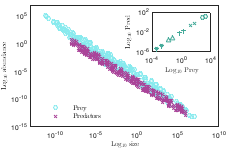


% plot the figure
plotDamuthInset;
figure
plotDamuth_v2;

## Exponent on the PPMR

What happens with changing the form of the trophic transfer efficiency to epislon = rho^psi?  

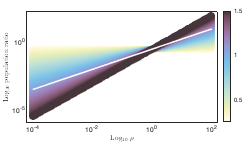

clear 
assignBaseParameters_attackform
rho =0.1;
colourScheme
epsilon = rho;

% set up input vectors
COEFF = coeffVector(r0,d0,b0,h0,K0,epsilon);
SIGMA = sigmaVector(sigmar,sigmad,sigmab,sigmahR,sigmahC,sigmaK);

% assign a base vector to assess impact of perturbing the exponent
% on the transfer efficiency

b=-4;
a = 2;
rho = 10.^((b-a).*rand(1000,1) + a);

rhoScaling = (0.25:0.01:1.5); 

% loop through the different values for rho and the exponents, get the
% equilibria population ratios for predator/prey
popdiff = zeros(length(rho),length(b));
    for k = 1:length(rhoScaling)
        for i=1:length(rho)
            popdiff(i,k) = getequilibPert(rho(i),1,rhoScaling(k),COEFF,SIGMA);
        end      
    end

% get value where psi exponent is 1 (white line on plot)
popdiff2 = zeros(length(rho),1);
    for j = 1:length(rho)
        popdiff2(j) = getequilibPert(rho(j),1,1,COEFF,SIGMA);
    end


% do the plot
figure
set(gcf,'units','centimeters','position',[10,10,8.6,5])

box on
hold on
cmap2 = paulTolColorMaps(length(rhoScaling),cols.continuous.iridRGB);
colororder(cmap2)
set(gca, 'YScale', 'log','XScale','log','xlim',[6E-5, 1.6E2],'ylim',[1E-6,2E2],'FontSize',6.5);

plot(rho,popdiff,'o');
h=plot(rho,popdiff2,'LineWidth',1.5,'LineStyle','-.','Color',[1,1,1]);
ax = ancestor(h, 'axes');
ax.XAxis.FontSize = 6.5;
ax.YAxis.FontSize = 6.5;
ax.XTick = [1E-4,1E-2,1E0,1E2];


xlabel('Log$_{10}$ $\rho$','Interpreter','latex'), ylabel('Log$_{10}$ population ratio','Interpreter','latex');
cb = colorbar;
colormap(cmap2);
caxis([0.25 1.5]);
ax = gca; axpos = ax.Position; cpos = cb.Position; cpos(3) = 0.5*cpos(3); cpos(1) = cpos(1) + 0.14;
axpos(3) =  1.22*axpos(3); cb.Position = cpos; ax.Position = axpos;

## Coexistence conditions

Examining the impact of the handling time (resource or consumer) parameter *h *on coexistence

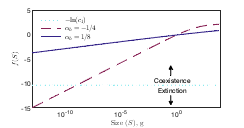

% set base parameters
assignBaseParameters_attackform
rho = 0.01;
epsilon = rho;
RECOEFF = recoeffVector(r0,d0,b0,h0,K0,epsilon,0.1,sigmar, sigmahR, sigmaK);

% set up a size range
minPredSize = -13;
maxPredSize = 4;
numPredators = 200;
m = 10.^((minPredSize-maxPredSize).*rand(numPredators,1) + maxPredSize);
m=sort(m);
c2 = 1/(RECOEFF(1));
c1 = (RECOEFF(2)/RECOEFF(3));


% assign coexistence function for sigmah=-1/4
sigmah = -1/4;
lhs1 = log(m.^(-sigmah - sigmad)) - log(1+ c2.* m.^( - sigmaK - sigmah - sigmab));

% assign coexistence function for sigmah=1/8
sigmah = 1/8;
lhs2 = log(m.^(-sigmah - sigmad)) - log(1+ c2.* m.^( - sigmaK - sigmah - sigmab));

% constant for the RHS
rhs = - log(c1).*ones(size(m,1),1);

% plot
figure
hold on
set(gcf,'units','centimeters','position',[10,10,8.6,4.5])

set(gca, 'XScale','log','xlim',[1E-13,1E4],'FontSize',6.5)
box on
plot(m,rhs,'-','LineWidth',1,'Color',cols.muted.cyan,'LineStyle',':')
plot(m,lhs1,'-','LineWidth',1,'Color',cols.muted.wine,'LineStyle',"--")
plot(m,lhs2,'-','LineWidth',1,'Color',cols.muted.indigo)
leg = legend('$-$ln$(c_1)$','$\alpha_h=-1/4$','$\alpha_h=1/8$','Interpreter','latex','location','northwest','FontSize',6.5,'box','off');
leg.ItemTokenSize = [20,18];

ylabel('$f(S)$','Interpreter','latex'), xlabel('Size ($S$), g','Interpreter','latex');
x = [0.7 0.7];
y = [0.41 0.486];
ar = annotation('textarrow',x,y,'String','Coexistence','FontSize',6.5);
ar.HeadLength = 4;
ar.HeadWidth = 5;
x = [0.7 0.7];
y = [0.256 0.18];
ar=annotation('textarrow',x,y,'String','Extinction','FontSize',6.5);
ar.HeadLength = 4;
ar.HeadWidth = 5;

### Behaviour of limit cycle

example of cycling for a single predator/prey pair;

Simulated, analytical and empirical results for the period of the cycle;

simulated results for the amplitude of the limit cycle

clear

% assign parameter values and set up input vectors
assignBaseParameters_attackform
colourScheme

r0 = 2.6E-6; 
d0 = 4E-6; 
h0 = 0.03; 
K0 = 0.06;
b0 =  .01;
rho = 0.1;

epsilon = rho.^1.3;
size1 = 1E-2;
sigmahR = 1/8;

epsilon = rho;

COEFF = coeffVector(r0,d0,b0,h0,K0,epsilon);
RECOEFF = recoeffVector(r0,d0,b0,h0,K0,epsilon, ... 
         rho,sigmar,sigmahR,sigmaK);
RESIGMA = resigmaVector(sigmar,sigmad,sigmab,sigmahR,sigmahC,sigmaK); 

% get the equilibria for initial values

[R1, C1]=equilibriaRescaled(size1,RECOEFF,RESIGMA);
mu = RECOEFF(1)*size1^RESIGMA(1);
gamma = RECOEFF(2)*size1^RESIGMA(2);
omega = RECOEFF(3)*size1^RESIGMA(3)

omega = 0.8651


% It's a stiff ODE at some points along the size range, so pass the
% analytic jacobian (also speed things up)
maxt = 800;
t=[0:0.001,maxt];
x0=[log(R1)+0.1,log(C1)+0.1];

% set ODE options
options = odeset('Vectorized','off','Jacobian',@jacobianRMAlogged,'RelTol',1E-3);

% solve ODE
[t,y] = ode15s(@(t,y) loggedODE(t,y,mu,gamma,omega), t, x0);

% find the stationary points along the ODE solutions (to get the period of
% the cycles)

stapoints = stationary(t,y(:,1),'max');
l = 2*(floor(size(t)/2));

% get base solution
recx = exp(y(:,1))./(b0*h0*rho^sigmahR*size1^(sigmab+sigmahR+sigmahC));
recy = exp(y(:,2)).*epsilon./(b0*h0*rho^sigmahR*size1^(sigmab+sigmahR+sigmahC));

% Get the simulated solutions for period of limit cycle
s = [1E-12,1E-10,1E-8,1E-6,1E-4,1E-2,1E0,1E2, 1E4];
timep = maxt./(r0*rho^sigmar*s.^sigmar);
period = timep./length(stapoints);
simCycPerC = log10(1./(period/(60*24*365*100)));

% plot to check the base solution is behaving
% figure
% hold on
% box on
% 
% plot(t./(r0*rho^sigmar*size1^sigmar),log10(recx./(b0*size1^sigmab * h0*rho^sigmahR * size1^(sigmahR+sigmahC))),'LineStyle','-','LineWidth',1,'Color','b')
% plot(t./(r0*rho^sigmar*size1^sigmar),log10(recy.*epsilon./(b0*size1^sigmab * h0*rho^sigmahR * size1^(sigmahR+sigmahC))),'LineStyle','-','LineWidth',1,'Color','r')
% legend('Prey','Predators')

Get  analytic solutions for the period of limit cycle across a size range

% how many predators and their sizes
numPredators=200;
minPredSize=-12;
maxPredSize = 4;

% set up vector of random masses, assign coefficients and scaling values
m = 10.^((minPredSize-maxPredSize).*rand(numPredators,1) + maxPredSize)';
COEFF = coeffVector(r0,d0,b0,h0,K0,epsilon);
SIGMA = sigmaVector(sigmar,sigmad,sigmab,sigmahR,sigmahC,sigmaK);

outperiod = zeros(length(m),1); % preassign output vec

% calculate analytic solutions
for i = 1:length(m)
    rho = 1E-1;
    
    r = COEFF(1).*rho.^(SIGMA(1)).*m(i).^(SIGMA(1));
    d = COEFF(2).*m(i).^(SIGMA(2));
    b = COEFF(3).*m(i).^(SIGMA(3));
    h = COEFF(4).*rho.^(SIGMA(4)).*m(i).^(SIGMA(4) + SIGMA(5));
    K = COEFF(5).*rho.^(SIGMA(6)).*m(i).^(SIGMA(6));
    
    outperiod(i) = 2 * pi * sqrt( (epsilon / (h * d)  + 1)/(r * d * (epsilon / (h * d)  - 1)) );
end

cpercent = log10(1./(outperiod/(60*24*365*100)));

% input the real data; scaled according to the literature units
realData = [];
hareLynx = [10000,(100*365)/3000]; % 3000 days per cycle, over a century
voleWeasel = [150,(100*365)/1600]; % 1600 days per cycle, over a century
ciliateBacteria = [1E-10, (100*24*365)/250];  % 250 hrs per cycle, over a century
daphnea = [5.9E-6, (100*365)/24]; % 24 days per cycle, over a century

calyciforus1 = [0.00056E-6, (100*365)/6];
calyciforus2 = [0.00056E-6, (100*365)/8];
toxo = [27E-3, (100*365)/(3*30)];
colpidium = [1E-10,(100*24*365)/100];
ecoli = [3E-13,(100*24*365)/30];
typhlod = [17E-6, (100*365)/85];

realData = [hareLynx;voleWeasel;ciliateBacteria;daphnea; ...
    calyciforus2;calyciforus1;toxo;colpidium;ecoli;typhlod];

Load heatmap data and solve symbolic equations for trace and determinant (takes ~30 seconds)

% load simulated amplitude of data from Mathematica; 
load('./testheatmap.mat')
heatmatrix = Expression1;
heatmatrix(imag(heatmatrix) ~= 0) = 0;
heatmatrix = rot90(heatmatrix);

load('./muvec.mat')
muvec = Expression1;

load('./gammavec.mat')
gammavec = Expression1;

omega2 = 0.5623;

% assign symbolic variable to solve for trace and determinant
syms gamma2

% set up analytic trace and determinant values to show coexistence boundaries

% solve for trace
tracesol = zeros(length(muvec),1);
for i=1:length(muvec)
    mu2 = muvec(i);
    S = solve(0 == -((omega2 *(gamma2 - gamma2 *mu2 + omega2 + mu2* omega2))/(gamma2 *mu2 *(gamma2 - omega2))), gamma2);
    tracesol(i) = double(S);
    
end

% solve for determinant
detsol = zeros(length(muvec),1);
for i = 1:length(muvec)
    mu2 = muvec(i);
    S= solve(0 == omega2/(gamma2-omega2) - mu2, gamma2);
    detsol(i) = double(S);
end

gamsort = sort(gammavec,'descend');
detsort = sort(detsol);

% fix values in the heatmap that are either infinite or should be zero
for i=1:length(muvec)
    for j=1:length(muvec)
        if gamsort(j) < tracesol(i)
            heatmatrix(j,i) = 0;
        end    
        if  gamsort(j) < detsol(i)
        heatmatrix(j,i) = NaN;
        end         
    end 
end

 % check dimensions match
size(detsol)

ans =     51     1


Plot the figure

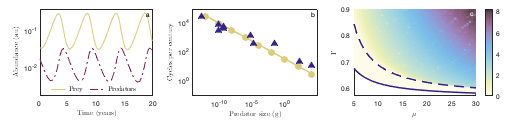

figure
set(gcf,'units','centimeters','position',[10,10,17.8,4.5])


ax7 = subtightplot(1, 3, 1, [0.0, 0.05],[0.25, 0.07],[0.08, 0.15]);
box on
hold on
plot(t(320:400)./(r0*rho^sigmar*size1^sigmar),log10(recx(320:400)),'LineStyle','-','LineWidth',1,'Color',cols.muted.sand)
plot(t(320:400)./(r0*rho^sigmar*size1^sigmar),log10(recy(320:400)),'LineStyle','-.','LineWidth',1,'Color',cols.muted.wine)
leg = legend({'Prey','Predators'},'Interpreter','latex', 'Location', [0.1,0.2,0.17,0.2],'color','none','Box','off');
leg.NumColumns = 2;
leg.ItemTokenSize = [15,9];
leg.FontSize = 6.5;
% leg.LineWidth = 2;

% xlim(ax7, [0, 1]);
ylim(ax7, [-2.75, -0.4]);
xlabel(ax7,'Time (years)','Interpreter','latex')
ylabel(ax7,'Abundance (au)','Interpreter','latex')
xlim(ax7,[1.3E7,1.5E7]);
ax7.XTickLabel = [0,5,10,15,20];
ax7.YTick = [-2,-1];

ax7.YTickLabel = {'10^{-2}','10^{-1}'};

ax7.XAxis.FontSize = 6.5;
ax7.YAxis.FontSize = 6.5;
annotation('textbox',[0.28 0.645 0.3 0.3],'BackgroundColor','none','EdgeColor','none','String','a','FontSize',6.5)


osc = subtightplot(1, 3, 2, [0.0, 0.05],[0.25, 0.07],[0.08, 0.07]);
box on

hold on
% plot(smallsizeOsc(:,1),log10(smallsizeOsc(:,3)), 'Color', cols.muted.olive,'LineWidth',2)
plot(log10(m),cpercent, 'Color',cols.muted.sand,'LineWidth',1.5)
plot(log10(s),simCycPerC,'o','Color',cols.muted.sand, 'MarkerSize',6,'MarkerFaceColor',cols.muted.sand)
% plot(dataSizes,log10(oscillationNums),'o','MarkerEdgeColor',cols.muted.rose,'MarkerSize',7,'LineWidth',2)
plot(log10(realData(:,1)),log10(realData(:,2)),'^','MarkerFaceColor',cols.muted.indigo,'MarkerEdgeColor',cols.muted.indigo,'MarkerSize',5)
ylabel(osc,'Cycles per century','Interpreter','latex')
xlabel(osc,'Predator size (g)','Interpreter','latex')
ylim(osc,[-1,5])
xlim(osc,[-14,5])

ax = gca;
ax.YTick = [0, 2, 4];
ax.XTick = [-10, -5, 0];

ax.YTickLabel = {'10^{0}', '10^{2}', '10^{4}'};
ax.XTickLabel = {'10^{-10}', '10^{-5}', '10^{0}'};
ax.XAxis.FontSize = 6.5;
ax.YAxis.FontSize = 6.5;
% set(gcf, 'Position', [50, 50, 600, 150]);
annotation('textbox',[0.605 0.645 0.3 0.3],'BackgroundColor','none','EdgeColor','none','String','b','FontSize',6.5)


cgridax = subtightplot(1, 3, 3, [0.0, 0.05],[0.25, 0.07],[0.0, 0.0]);
cdata = heatmatrix;

cmap2 = paulTolColorMaps(100,cols.continuous.iridRGB);
colororder(cmap2)
h=pcolor(muvec,gamsort,cdata);
set(h,'EdgeColor', 'none')
ax = ancestor(h, 'axes');

ax.XAxis.FontSize = 6.5;
ax.YAxis.FontSize = 6.5;
colormap(cmap2)
cbar = colorbar;
cbar.FontSize = 6.5;

ax = gca; axpos = ax.Position; cpos = cbar.Position; cpos(3) = 0.7*cpos(3); cpos(1) = cpos(1)+0.03;
axpos(3) = 0.81*axpos(3); cbar.Position = cpos; ax.Position = axpos;


hold on
plot(cgridax,muvec,tracesol,'LineWidth',1.5,"Color",cols.muted.indigo,'LineStyle', "- -")
plot(cgridax,muvec,detsol,'LineWidth',1.5,"Color",cols.muted.indigo)
xlabel('\mu','Interpreter','tex')
ylabel('\Gamma','Interpreter','tex')
annotation('textbox',[0.92 0.65 0.3 0.3],'BackgroundColor','none','EdgeColor','none','String','c','FontSize',6.5,'Color','w')

### Generate the sensitivity figure

The sensitivity equations are in the function file sensitivityODE.m

clear

% nominal values for parameters
a = 7.1; 
c = 1.1;
b = 0.7;

% values to pass to simulation
inputOmega=b;
inputGamma=c;
inputMu=a;

% initial values
initX = inputOmega/(inputGamma-inputOmega);
initY = (1 + initX)*(1-initX/inputMu)/inputGamma;

initX1 = inputOmega/(inputGamma-inputOmega) * 0.10;
initY1 = (1 + initX)*(1-initX/inputMu)/inputGamma*10;

% assign number of time steps, get output of sensitivity functions
tlength = 90;
[t,y] = sensitivtyFunctionsSimulation(inputMu,inputGamma,inputOmega,initX,initY,tlength);
[t1,y1] = sensitivtyFunctionsSimulation(inputMu,inputGamma,inputOmega,initX1,initY1,tlength);


Plot the results

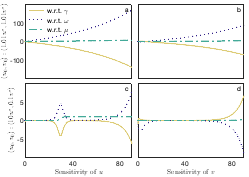


colourScheme;
figure
set(gcf,'units','centimeters','position',[10,10,8.6,6])

ax1 = subtightplot(2, 2, 1, [0.025, 0.025]);
box on
hold on
h = plot(t,sign(y(:,[3,5,7])).*abs(y(:,[3,5,7])).^(1/2),'Linewidth',1);
ax = ancestor(h(1), 'axes');
xticks(ax,[0 40 80]);
xticklabels(ax,[]);

xlim(ax,[0,tlength]);
ylim(ax,[-200,200]);
yticks(ax,[-100 0 100]);

ylabel(ax,'$(u_0,v_0): (1.01u^*,1.01v^*)$',"Interpreter",'latex')

set(h, {'color'}, {cols.muted.sand; cols.muted.indigo;cols.muted.teal});
set(h, {'LineStyle'}, {'-';':';'-.'});
annotation('textbox',[0.48 0.69 0.3 0.3],'BackgroundColor','none','EdgeColor','none','String','a','FontSize',6.5)


ax2 = subtightplot(2, 2, 2, [0.025, 0.025]);
h = plot(t,sign(y(:,[4,6,8])).*abs(y(:,[4,6,8])).^(1/2),'Linewidth',1);
ax2 = ancestor(h(1), 'axes');
xlim(ax2,[0,tlength]);
xticks(ax2,[0  40  80]);
xticklabels(ax2,[]);
set(h, {'color'}, {cols.muted.sand; cols.muted.indigo;cols.muted.teal});
set(h, {'LineStyle'}, {'-';':';'-.'});
annotation('textbox',[0.93 0.69 0.3 0.3],'BackgroundColor','none','EdgeColor','none','String','b','FontSize',6.5)

ax2.FontSize=6.5;
ax2.XLabel.FontSize=6.5;
ylim(ax2,[-200,200]);
yticklabels(ax2,[])

BL = legend('w.r.t. \gamma','w.r.t. \omega','w.r.t. \mu','location','northwest');
legend boxoff                   % Hides the legend's axes (legend border and background)
BL.FontSize = 6.5;
BL.ItemTokenSize = [15,9];
BL.Position = [0.15,0.86,0.0,0.0];


ax3 = subtightplot(2, 2, 3, [0.025, 0.025]);
box on
hold on
h = plot(t1,sign(y1(:,[3,5,7])).*abs(y1(:,[3,5,7])).^(1/2),'Linewidth',1);
ax3 = ancestor(h(1), 'axes');
xticks(ax3,[0  40  80]);

xlim(ax3,[0,tlength]);
ylim(ax3,[-10,10]);
yticks(ax3,[-5 0 5]);
ylabel(ax3,'$(u_0,v_0): (10u^*,0.1v^*)$',"Interpreter",'latex')
set(h, {'color'}, {cols.muted.sand; cols.muted.indigo;cols.muted.teal});
set(h, {'LineStyle'}, {'-';':';'-.'});
annotation('textbox',[0.48 0.24 0.3 0.3],'BackgroundColor','none','EdgeColor','none','String','c','FontSize',6.5)


ax4 = subtightplot(2, 2, 4, [0.025, 0.025]);
h = plot(t1,sign(y1(:,[4,6,8])).*abs(y1(:,[4,6,8])).^(1/2),'Linewidth',1);
ax4 = ancestor(h(1), 'axes');
xticks(ax4,[0  40  80]);


xlim(ax4,[0,tlength]);
ylim(ax4,[-10,10]);
yticklabels(ax4,[])

xlabel(ax4,'Sensitivity of $v$',"Interpreter",'latex')
xlabel(ax3,'Sensitivity of $u$',"Interpreter",'latex')

set(h, {'color'}, {cols.muted.sand; cols.muted.indigo;cols.muted.teal});
set(h, {'LineStyle'}, {'-';':';'-.'});
annotation('textbox',[0.93 0.24 0.3 0.3],'BackgroundColor','none','EdgeColor','none','String','d','FontSize',6.5)

ax.FontSize=6.5;
ax2.FontSize=6.5;
ax3.FontSize=6.5;
ax4.FontSize=6.5;


tightfig;

## Utility functions

Assign some short utility functions which are to keep the .mlx file tidy

function COEFF = coeffVector(r0,d0,b0,h0,K0,epsilon)
    % Creates the coefficient vector 
    COEFF = [r0,d0,b0,h0,K0,epsilon];
end

function SIGMA = sigmaVector(sigmar,sigmad,sigmab,sigmahR,sigmahC,sigmaK)
sigmah = sigmahR + sigmahC;
% Creates the sigma vector
    SIGMA = [sigmar,sigmad,sigmab,sigmahR,sigmahC,sigmaK];
end

function RECOEFF = recoeffVector(r0,d0,b0,h0,K0,epsilon,rho, ...
    sigmar, sigmahR, sigmaK)
    % creates the rescaled coefficients

    mu0 = K0*b0*h0*rho^(sigmaK + sigmahR);
    gamma0 = epsilon/(r0*h0*rho^(sigmar + sigmahR));
    omega0 = d0/((rho^sigmar)*r0);
    RECOEFF = [mu0,gamma0,omega0];
end


function RESIGMA = resigmaVector(sigmar,sigmad,sigmab, sigmahR,sigmahC,sigmaK)
    % creates the rescaled exponents
    sigmamu = sigmaK + sigmahR + sigmahC + sigmab;
    sigmagamma = - sigmahR - sigmahC - sigmar;
    sigmaomega = sigmad - sigmar;
        
    RESIGMA = [sigmamu,sigmagamma,sigmaomega];
end



function popdiff = getPopDiff(m,rho, COEFF,SIGMA)    
    [R, C]=rmaEquilibria_attack(m,rho,COEFF,SIGMA);   
    popdiff = C/R;
end


function popdiff = getequilibPert(rho,a,b,COEFF,SIGMA)
       
    epsilon = a*rho^b;
    
COEFF(6) = epsilon;
m = 1E-4;
[R, C]=rmaEquilibria_attack(m,rho,COEFF,SIGMA);

popdiff = C/R;

end